## 题目1

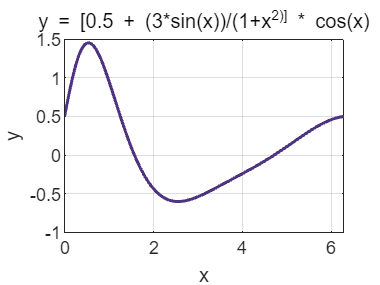

x = linspace(0, 2*pi, 101);
y = (0.5 + (3*sin(x))./(1+x.^2)) .* cos(x);

figure;
plot(x, y, 'Color',[0.3,0.2,0.5] ,'LineWidth', 1.5);
title('y = [0.5 + (3*sin(x))/(1+x^2)] * cos(x)');
xlabel('x');
ylabel('y');
grid on;

## 题目2

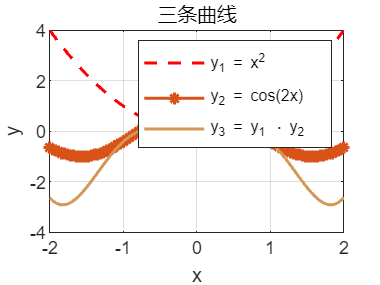

x = linspace(-2, 2, 100);
y1 = x.^2;
y2 = cos(2*x);
y3 = y1 .* y2;
% (1) 用不同颜色和线型绘制
figure;
plot(x, y1,'r--','LineWidth', 1.5); hold on;
plot(x, y2, '*-', 'LineWidth', 1.5);
plot(x, y3, 'Color',[rand(1,3)], 'LineWidth', 1.5);
legend('y_1 = x^2', 'y_2 = cos(2x)', 'y_3 = y_1 \cdot y_2');
title('三条曲线');
xlabel('x');
ylabel('y');
grid on;

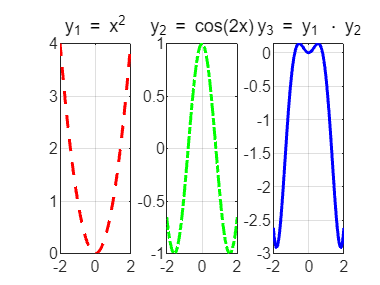


% (2) 子图形式绘制
figure;
subplot(1, 3, 1);
plot(x, y1, 'r--', 'LineWidth', 1.5);
title('y_1 = x^2');
grid on;

subplot(1, 3, 2);
plot(x, y2, 'g-.', 'LineWidth', 1.5);
title('y_2 = cos(2x)');
grid on;

subplot(1, 3, 3);
plot(x, y3, 'b-', 'LineWidth', 1.5);
title('y_3 = y_1 \cdot y_2');
grid on;

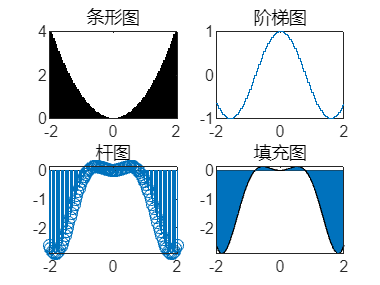


% (3) 条形图、阶梯图、杆图和填充图
figure;
subplot(2, 2, 1);
bar(x, y1);
title('条形图');

subplot(2, 2, 2);
stairs(x, y2);
title('阶梯图');

subplot(2, 2, 3);
stem(x, y3);
title('杆图');

subplot(2, 2, 4);
area(x, y3);
title('填充图');

## 题目3

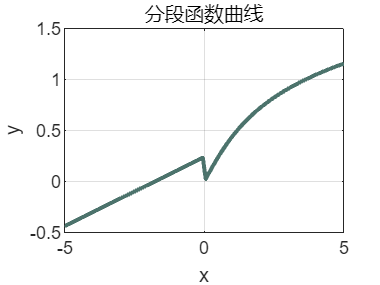

% 3. 绘制分段函数曲线
x = linspace(-5, 5, 100);
y = zeros(size(x));
y(x <= 0) = (x(x <= 0) + sqrt(pi)) / exp(2);
y(x > 0) = 0.5 * log(x(x > 0) + sqrt(1 + x(x > 0).^2));

figure;
plot(x, y, 'Color',[rand(1,3)], 'LineWidth', 2);
title('分段函数曲线');
xlabel('x');
ylabel('y');
grid on;

## 题目4

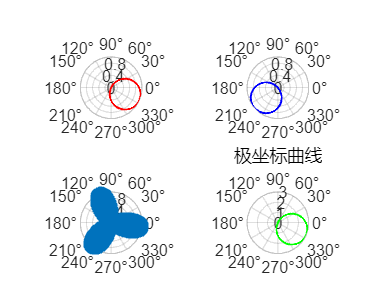

% 4. 极坐标曲线
theta = linspace(0, 2*pi, 1000);
a = 1; b = 1; n = 2;
r = a * sin(b * theta + n);

a1 = 1; b1=1 ; n1 = 4;
r1 = a1 * sin(b1 * theta + n1);

a2 = 1; b2 = 3 ; n2 = 2;
r2 = a2 * sin(b2 * theta + n2);

a3 = 3; b3 = 1 ; n3 = 2;
r3 = a3 * sin(b3 * theta + n3);

figure;
subplot(2, 2, 1);
polarplot(theta, r, 'r-', 'LineWidth', 1);
subplot(2, 2, 2);
polarplot(theta, r1, 'b-', 'LineWidth', 1);
subplot(2, 2, 3);
polarplot(theta, r2, 'o-', 'LineWidth', 1);
subplot(2, 2, 4);
polarplot(theta, r3, 'g-', 'LineWidth', 1);
title('极坐标曲线');

## 题目5

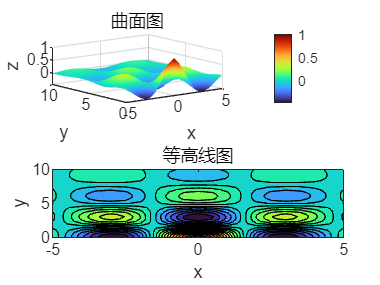

% 5. 绘制曲面图和等高线图
x = linspace(-5, 5, 21);
y = linspace(0, 10, 31);
[X, Y] = meshgrid(x, y);
Z = cos(X).* cos(Y).*exp(- sqrt(X.^2 + Y.^2)/4);

figure;
subplot(2, 1, 1);
surf(X, Y, Z);
title('曲面图');
xlabel('x');
ylabel('y');
zlabel('z');
shading interp; % 插值着色
colormap("turbo"); % 使用 parula 颜色映射
colorbar; % 添加颜色条

subplot(2, 1, 2);
contourf(X, Y, Z, 20); % 绘制等高线图
title('等高线图');
xlabel('x');
ylabel('y');
shading interp; % 插值着色

## 题目6

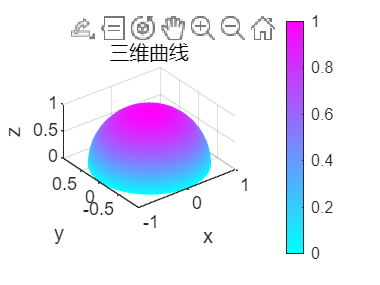

% 6. 绘制三维曲面
t = linspace(0, 3*pi, 100);
s = linspace(0, 0.5*pi, 100);

% 使用 meshgrid 生成二维网格
[T, S] = meshgrid(t, s);

% 计算 x, y, z
X = cos(S) .* cos(T);
Y = cos(S) .* sin(T);
Z = sin(S);

% 绘制三维曲面
figure;
surf(X, Y, Z);
shading interp; % 插值着色
colormap("cool"); 
colorbar; % 添加颜色条
title('三维曲线');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
view(3); % 设置视角为三维
axis equal; % 设置坐标轴比例相等